#### `ACTIVIDAD #1`

%para cuando a=1
H1=tf(1,[1 1])

H1 =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



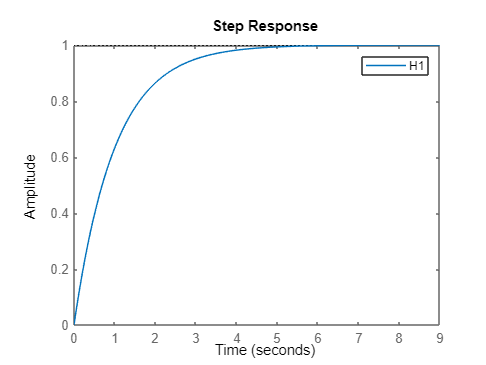

step(H1)
legend


%para cuando a=3
H2=tf(3,[1 3])

H2 =
 
    3
  -----
  s + 3
 
Continuous-time transfer function.



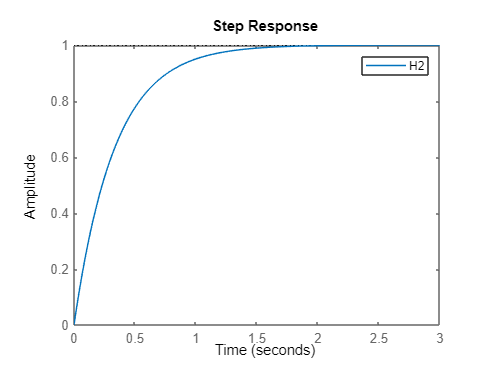

step(H2)
legend


%para cuando a=5
H3=tf(5,[1 5])

H3 =
 
    5
  -----
  s + 5
 
Continuous-time transfer function.



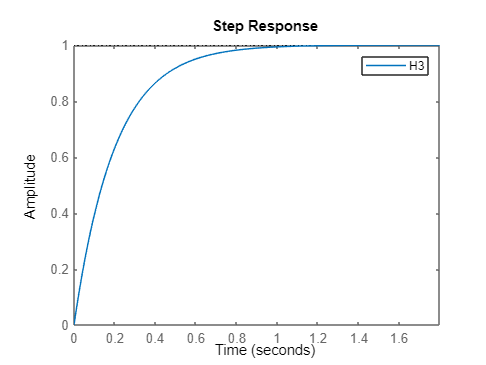

step(H3)
legend

#### PUNTO #2

H4=tf(25,[1 4 25])

H4 =
 
        25
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.



step(H4)
pole(H4)

ans =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i


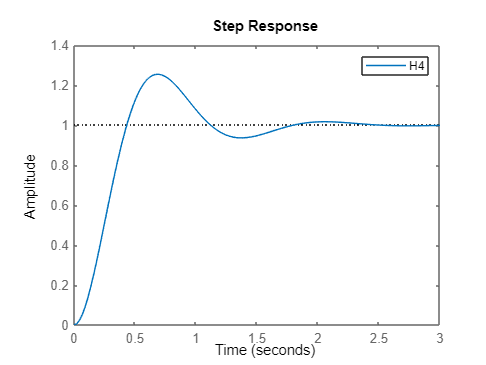

legend

# **PUNTO #2 INCISOS , MODIFICACION DE POLOS**

#### MODIFICAR POLOS REALES Y IMAGINARIO

%Original
a=4;
b=25;
HJ=tf(b,[1 a b])

HJ =
 
        25
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.



%step(HJ)
%legend
pole(HJ)

ans =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i



%Modificada
a1=8;
b1=37;
HK=tf(b1,[1 a1 b1])

HK =
 
        37
  --------------
  s^2 + 8 s + 37
 
Continuous-time transfer function.



%step(HJ)
%legend
pole(HK)

ans =   -4.0000 + 4.5826i
  -4.0000 - 4.5826i


#### MULTIPLICACION DE FUNCIONES DE TRANSFERENCIA

%funcion de transferencia a
H4=tf(25,[1 4 25])

H4 =
 
        25
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.



step(H4)
pole(H4)

ans =   -2.0000 + 4.5826i
  -2.0000 - 4.5826i


legend

HQ=H4*1/s;
feedback(HQ,1)

ans =
 
            25
  -----------------------
  s^3 + 4 s^2 + 25 s + 25
 
Continuous-time transfer function.



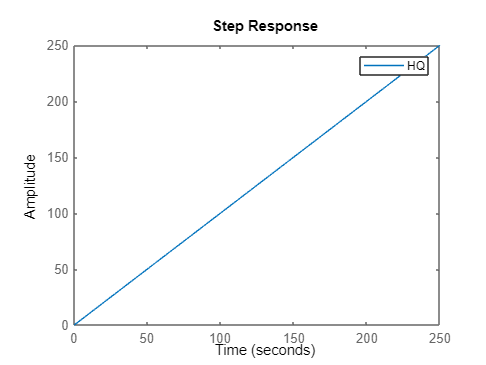

step(HQ)
legend



%K=200
HA=tf(200,[1 200])

HA =
 
    200
  -------
  s + 200
 
Continuous-time transfer function.



step(HA)
pole(HA)

ans = -200

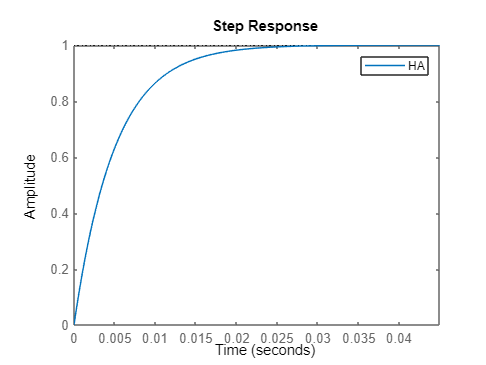

legend


%K=20
HB=tf(20,[1 20])

HB =
 
    20
  ------
  s + 20
 
Continuous-time transfer function.



step(HB)
pole(HB)

ans = -20

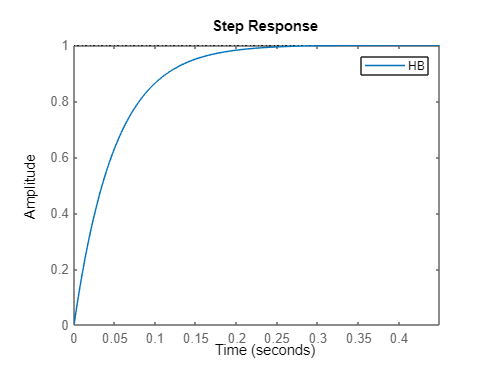

legend


%K=2
HC=tf(2,[1 2])

HC =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.



step(HC)
pole(HC)

ans = -2

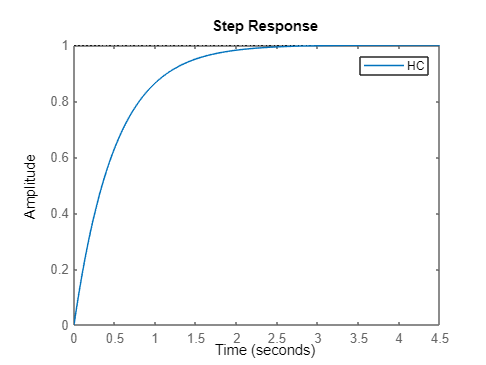

legend


A1=series(H4, HA)

A1 =
 
              5000
  ----------------------------
  s^3 + 204 s^2 + 825 s + 5000
 
Continuous-time transfer function.



legend
A2=series(H4, HB)

A2 =
 
             500
  --------------------------
  s^3 + 24 s^2 + 105 s + 500
 
Continuous-time transfer function.



legend
A3=series(H4, HC)

A3 =
 
            50
  -----------------------
  s^3 + 6 s^2 + 33 s + 50
 
Continuous-time transfer function.



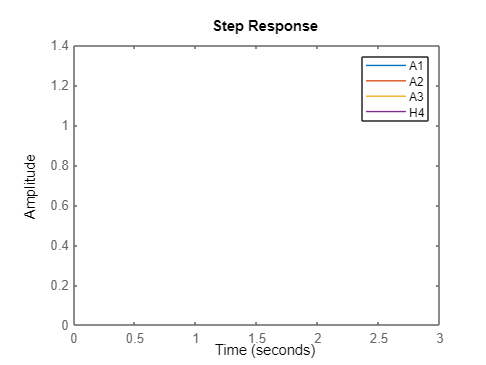

legend
step(A1,A2,A3,H4)
legend

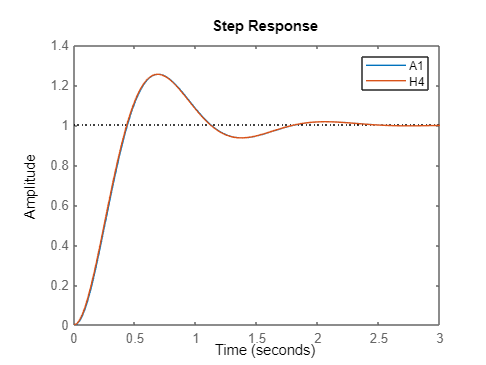

step(A1,H4)
legend

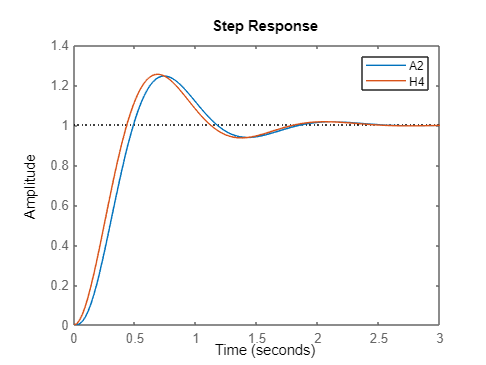

step(A2,H4)
legend

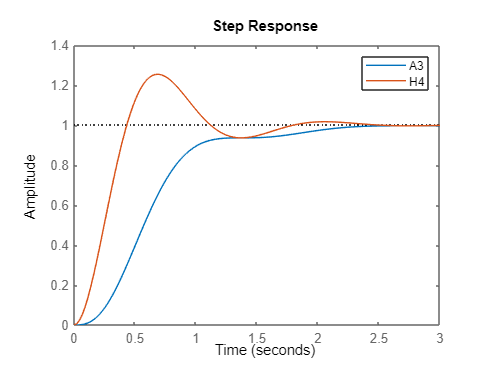

step(A3,H4)
legend


%para los otros valores de k

%K=10
HZ=tf(10,[1 10])

HZ =
 
    10
  ------
  s + 10
 
Continuous-time transfer function.



step(HZ)
pole(HZ)

ans = -10

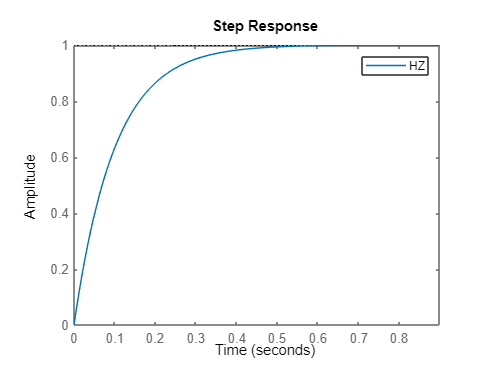

legend


%K=2
HX=tf(2,[1 2])

HX =
 
    2
  -----
  s + 2
 
Continuous-time transfer function.



step(HX)
pole(HX)

ans = -2

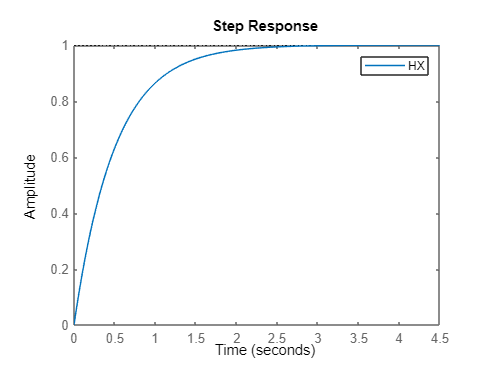

legend


%K=-10
HV=tf(-10,[1 -10])

HV =
 
   -10
  ------
  s - 10
 
Continuous-time transfer function.



step(HV)
pole(HV)

ans = 10

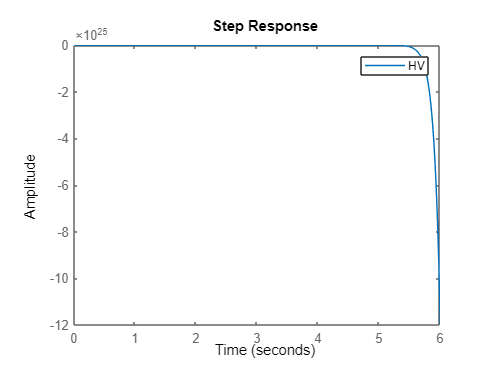

legend


A4=series(H4, HA)

A4 =
 
              5000
  ----------------------------
  s^3 + 204 s^2 + 825 s + 5000
 
Continuous-time transfer function.



legend
A5=series(H4, HB)

A5 =
 
             500
  --------------------------
  s^3 + 24 s^2 + 105 s + 500
 
Continuous-time transfer function.



legend
A6=series(H4, HC)

A6 =
 
            50
  -----------------------
  s^3 + 6 s^2 + 33 s + 50
 
Continuous-time transfer function.



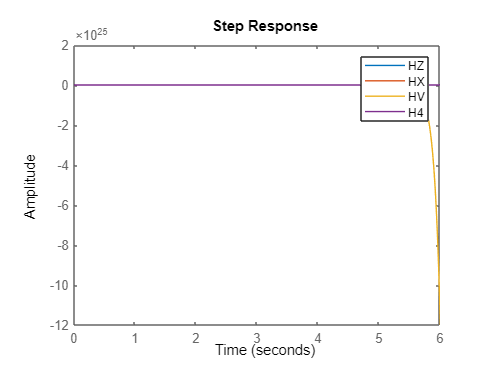

legend

step(HZ,HX,HV,H4)
legend